# Examine Images from Audi Q7 Crash Test

The following code loads and displays the structure array containing crash test data for several cars.

load ./data/crashDataStruct.mat
crashDataStruct

crashDataStruct = 1×6 struct array with fields:
    car
    carSize
    testInfo
    impactSpeed
    description
    data
    photos


## Task 1

In this activity, you will extract information about the Audi Q7 crash test.

audi = crashDataStruct(1)

audi = struct with fields:
            car: "2018 Audi Q7"
        carSize: [2380 5025 1956]
       testInfo: [2×1 string]
    impactSpeed: 61.6900
    description: "Displacement  measurements in mm from the left front seat (lower, middle, and upper ribs) and left back seat (lower abdomen, lower/middle ribs, upper ab, and upper rib)."
           data: {[3193×1 double]  [3402×1 double]  [2861×1 double]  [3269×1 double]  [1308×1 double]  [3312×1 double]  [3033×1 double]  [3247×1 double]}
         photos: {3×1 cell}


## Task 2

You can view a description of the test in the `testInfo` field.

whyAndHow = audi.testInfo

whyAndHow = 2×1 string array
    "OBJECTIVE: VEHICLE CRASHWORTHINESS AND OCCUPANT RESTRAINT PERFORMANCE DATA"
    "TEST CONFIGURATION: IMPACTOR INTO VEHICLE"


## Test 3

Click and mouse over the string array to see the complete text describing why and how the car was tested. Here you will view a post-crash image of the car to see the effect.

im = audi.photos

im = 3×1 cell array
    {312×467×3 uint8}
    {312×467×3 uint8}
    {312×467×3 uint8}


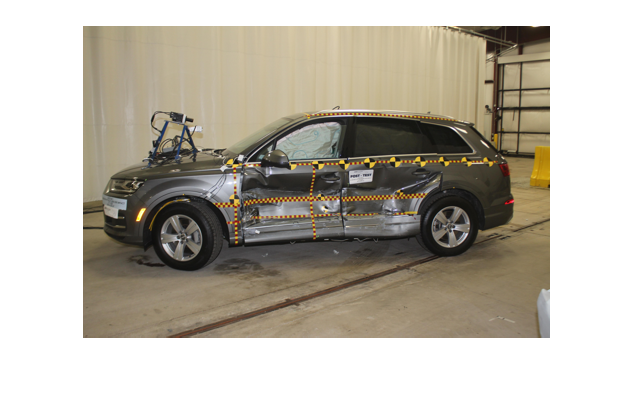

imshow(im{2})